We will be repeating the same calculations but for a p-wave, where n = 1

Therefore, the equations will be:


$$\frac{dY}{dx}= \frac{-\lambda}{x^3}(Y^2-Y_{EQ}^2)$$


Repeating the previous assumptions:

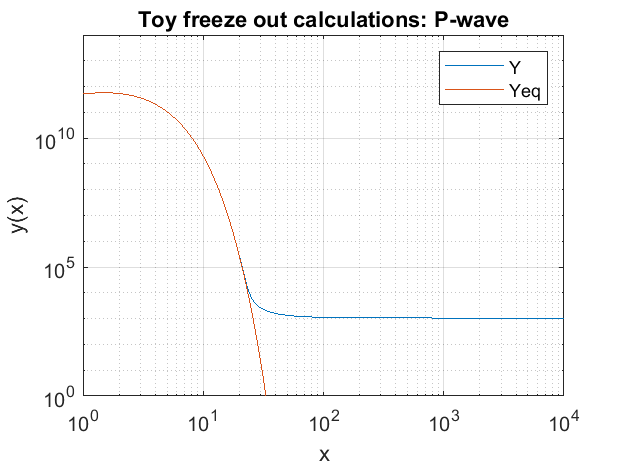

m = 300;
g = 100;
sig = 1e-9; 
mpl = 2.44e19;

f = @(x, y) (-1/(x.^3)).*(y.^2-(0.192*m*mpl*sig*(x.^(3/2)).*exp(-x)).^2); 
xrange = [1, 1e4];
y0 = 0.192*m*mpl*sig*exp(-1);
[x, y] = ode15s(f, xrange, y0);

figure;
loglog(x, y);
hold on
yeq = 0.192*m*mpl*sig*(x.^(3/2)).*exp(-x);
loglog(x, yeq);
xlabel("x");
ylabel("y(x)");
xlim([1, 1e4]);
ylim([1, 1e14]);
title("Toy freeze out calculations: P-wave");
grid on


legend('Y', 'Yeq'),

hold off

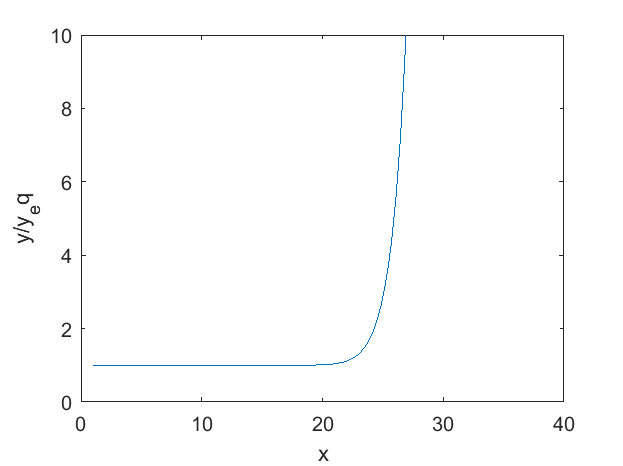


r = y ./ yeq; 
figure;
plot(x, r);
xlabel("x");
ylabel("y/y_eq");
ylim([0, 10]);
xlim([0, 40]);